# **RLC Circuits**

V = IR + LI' + Q/C

V = Q'R + Q''L + Q/C

0 = L

*Q'' + R*Q' + (1/C)*Q

w^2=(1/CL) -> 

Q''+2zw*Q'+w^2*Q = 0

clear
close all

syms z w x(t) x0

myode = diff(x,2) + 2*z*w*diff(x)+x*w^2 == 0

$$myode(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,z\,w\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)\,w^{2}=0$$


dx = diff(x)

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

mycond = [x(0)==x0 dx(0)==0]

$$mycond = \left(\begin{array}{cc} x\left(0\right)=x_{0} & \left({\left(\frac{\partial }{\partial t}x\left(t\right)\right)|}_{t=0}\right)=0 \end{array}\right)$$


x = dsolve(myode, mycond)

$$x = \begin{array}{l} \frac{x_{0}\,{\mathrm{e}}^{t\,\left(w\,\sigma_{1}-w\,z\right)}\,\left(z+\sigma_{1}\right)}{2\,\sigma_{1}}-\frac{x_{0}\,{\mathrm{e}}^{-t\,\left(w\,\sigma_{1}+w\,z\right)}\,\left(z-\sigma_{1}\right)}{2\,\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left(z-1\right)\,\left(z+1\right)} \end{array}$$

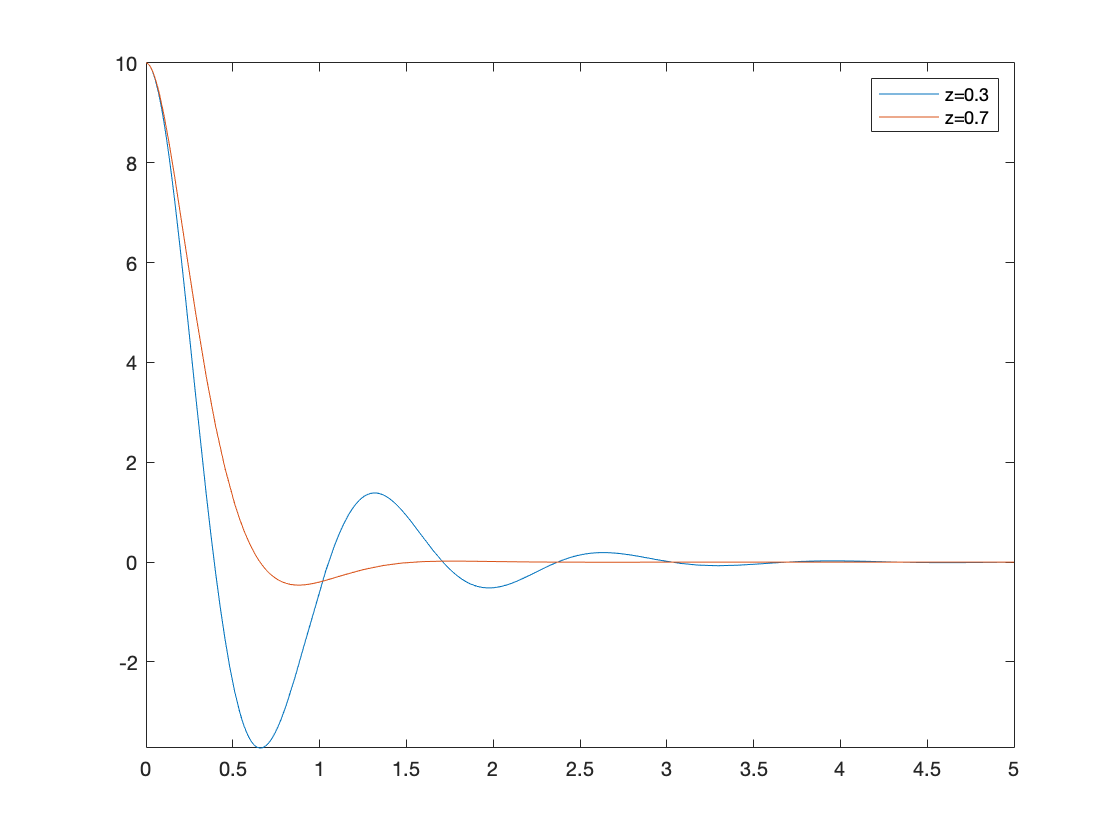


fplot (subs(x, [x0 z w], [10 0.3 5]), [0 5])

hold on
fplot (subs(x, [x0 z w], [10 0.7 5]), [0 5])
legend('z=0.3', 'z=0.7')